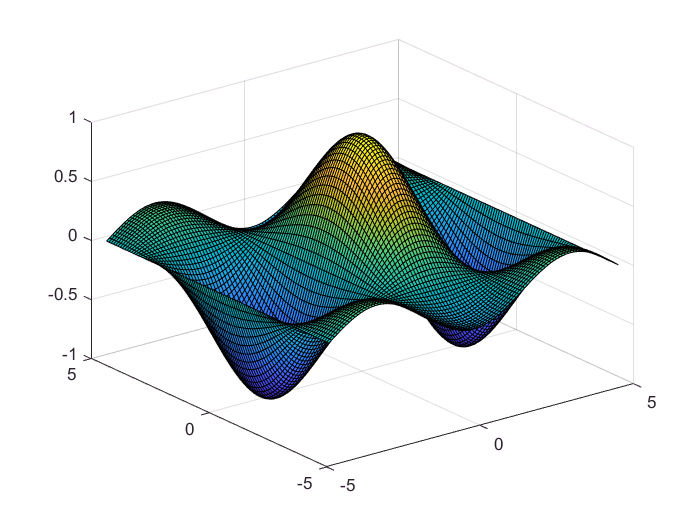

x=linspace(-1.5*pi,1.5*pi);
y=linspace(-1.5*pi,1.5*pi);
[x,y]=meshgrid(x,y);
z=cos(x).*sin(y)./y+eps;
surf(x,y,z);

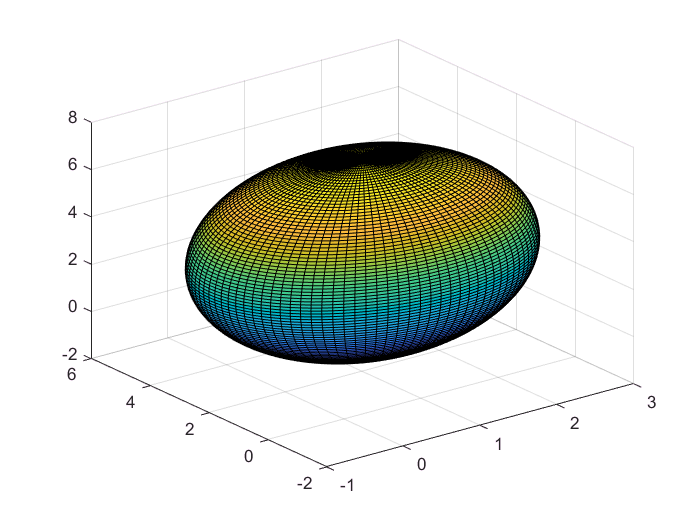

ellipsoid(1,2,3,2,3,4,100);

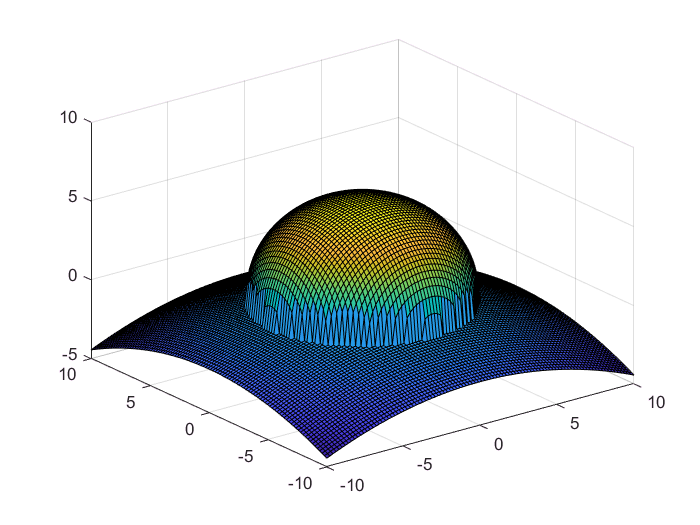

clear;
x=linspace(-10,10);
y=linspace(-10,10);
[x,y]=meshgrid(x,y);
N=size(x,2);
M=size(y,1);
Z=zeros(N,M);
for i = 1:N
    for j = 1:M
        if sqrt(x(j,i).^2+y(j,i).^2)<6
            z(i,j)=sqrt(36-x(j,i).^2-y(j,i).^2);
        else
            z(i,j)=-(x(j,i).^2+y(j,i).^2)/45;
            
        end
    end
    
end
       surf(x,y,z) 

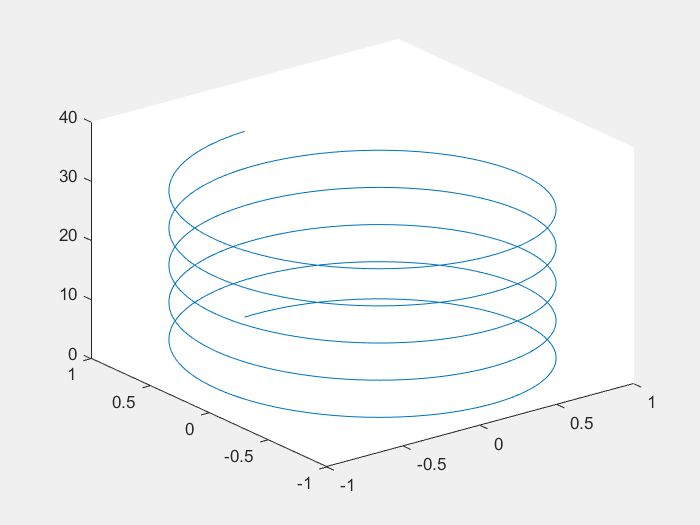

       t=0:pi/50:10*pi;
plot3(sin(t),cos(t),t)
rotate3d

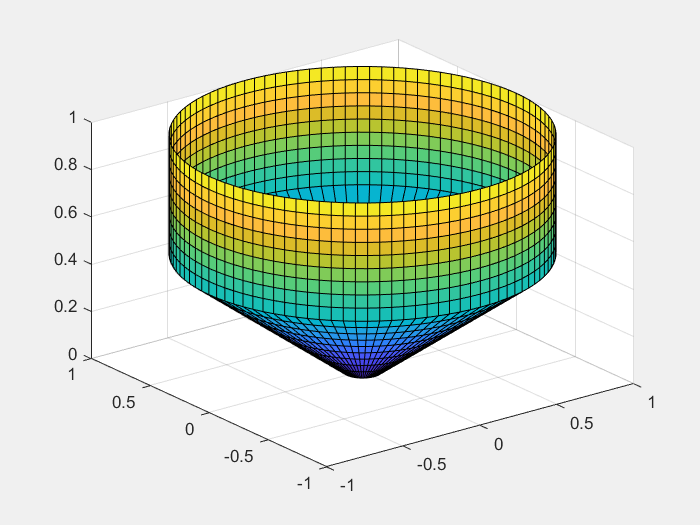

r=(0.1:0.1:1);
R=[r,1,1,1,1,1,1,1,1,1];
[x,y,z]=cylinder(R,100);
surf(x,y,z)